# Script to find CCEPs, characterize height, prominance, half width max

Switch in polarity? 

half width?

prominance?

close all;clearvars; clc

Z_ConstantsLarryDavidStephen;

sid = input('what is the SID?\n','s');

load(fullfile(META_DIR, [sid '_StimulationAndCCEPs']));


% look at electrode of interest .
% for 0b5a2e it'll be 14 to start  , also look at 31 and 23 
figure
data = ECoGData(:,:,31);
ax1  = subplot(3,1,1)

ax1 =   Axes with properties:

             XLim: [-0.0500 0.1500]
             YLim: [-3.0000e-04 2.0000e-04]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(t,data);
ylim([-300e-6 200e-6])

ax2 = subplot(3,1,2)

ax2 =   Axes with properties:

             XLim: [-0.0500 0.1500]
             YLim: [-0.0200 0.0200]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4097 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


data_deriv = diff(data);
plot(t(1:end-1),data_deriv);


ax3 = subplot(3,1,3)

ax3 =   Axes with properties:

             XLim: [-0.0500 0.1500]
             YLim: [-0.0200 0.0200]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


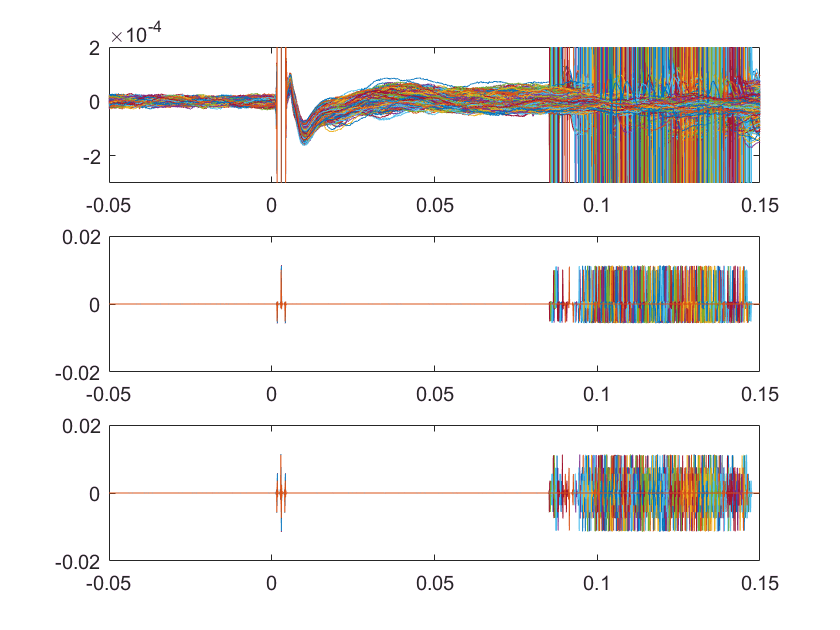

data_deriv_2 = diff(data_deriv);
plot(t(1:end-2),data_deriv_2);

linkaxes([ax1,ax2,ax3],'x')

% TV reg diff
% TVRegDiff( noisyabsdata, 500, 0.2, [], 'small', 1e-6, 0.01, 1, 0 )
data_derivT = [];
data_sub = data(:,1000);

%data_deriv= TVRegDiff(data_sub,500,50,[],'small',1e-9,0.01,1,0);
data_deriv= TVRegDiff(data_sub,500,5,[],'small',1e-9,0.01,1,0);


data_deriv_2 = TVRegDiff(data_sub,500,50,[],'small',1e-9,0.01,1,0);

figure
ax1  = subplot(3,1,1)

ax1 =   Axes with properties:

             XLim: [0 2500]
             YLim: [-0.0100 0.0100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.1949]
            Units: 'normalized'

  Show all properties


plot(data_sub);

ax2 = subplot(3,1,2)

ax2 =   Axes with properties:

             XLim: [0 2500]
             YLim: [-2.0000e-07 2.0000e-07]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4097 0.7750 0.1949]
            Units: 'normalized'

  Show all properties


plot(data_deriv);

ax2 = subplot(3,1,3)

ax2 =   Axes with properties:

             XLim: [0 2500]
             YLim: [-2.0000e-04 2.0000e-04]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.1949]
            Units: 'normalized'

  Show all properties


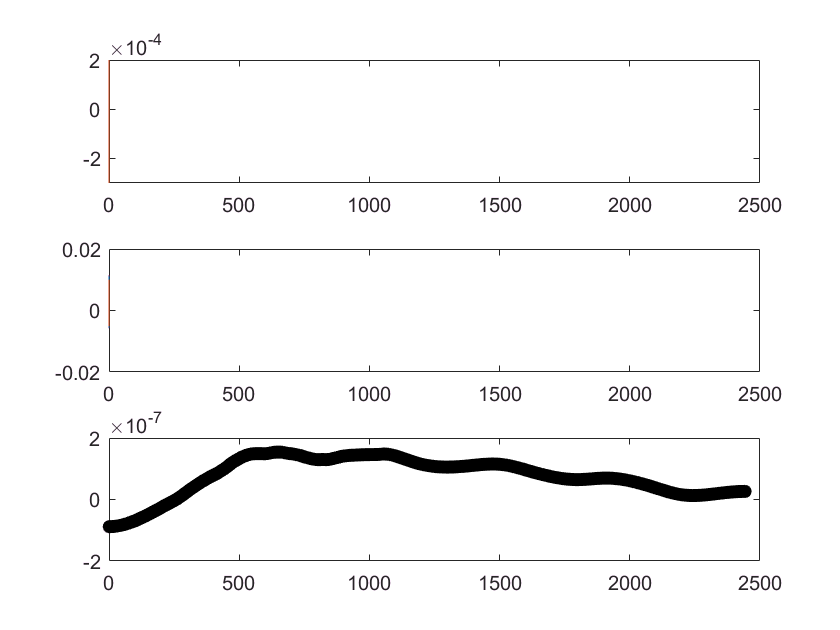

plot(data_deriv_2);


linkaxes([ax1,ax2,ax3],'x')

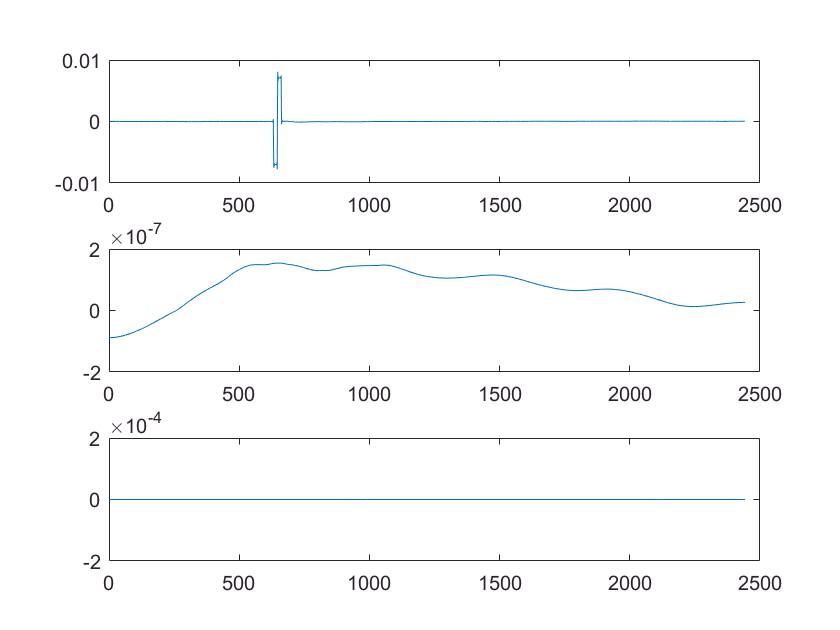

ylim([-200e-6 200e-6])

% some ideas from stavros cycle trigger stim
% 2 ms positive/negative voltage samples
% second derivative close ot zero
% difference etween sample with maximum deflection neighboring 2 samples before 




[pks,locs,w,p]= findpeaks(data(i,t(t>0.01 & t <0.05)),t(t>0.01 & t <0.05),'Annotate','extents','WidthReference','halfheight')

Error using findpeaks
Expected Y to be a vector.

Error in findpeaks>parse_inputs (line 191)
validateattributes(Yin,{'numeric'},{'nonempty','real','vector'},...

Error in findpeaks (line 134)
  = parse_inputs(Yin,varargin{:});


% average
figure
[pks,locs,w,p]= findpeaks(abs(mean(data((t>0.01 & t <0.05),:),2)),t(t>0.01 & t <0.05),'Annotate','extents','WidthReference','halfheight','MinPeakDistance',0.005)

pks =    1.0e-04 *

    0.0517
    0.6709
    0.6754
    0.6750
    0.6754
    0.6746
    0.6744


locs =     0.0102    0.0269    0.0275    0.0278    0.0279    0.0282    0.0284


w =     0.0011    0.0096    0.0007    0.0002    0.0002    0.0002    0.0094


p =    1.0e-04 *

    0.0002
    0.0002
    0.0006
    0.0002
    0.6746
    0.0004
    0.0005


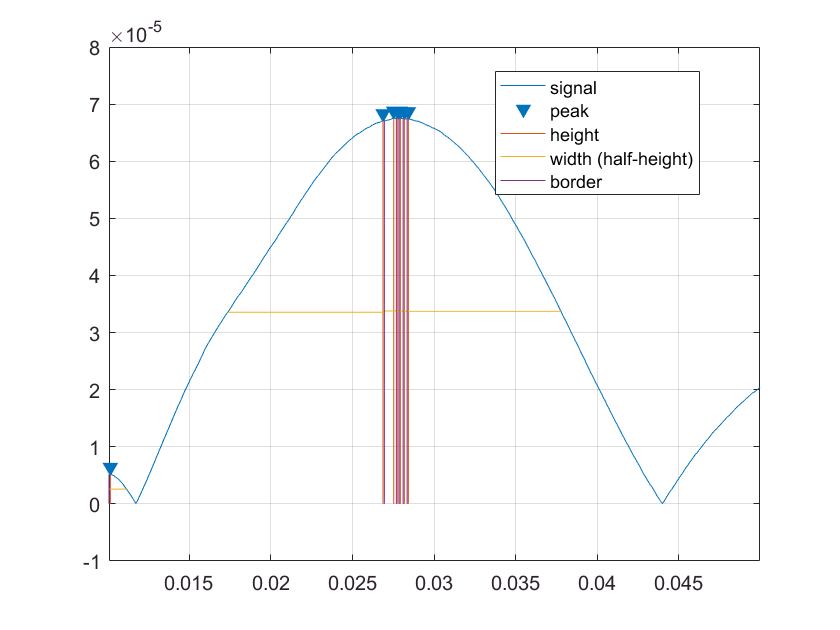

findpeaks(abs(mean(data((t>0.01 & t <0.05),:),2)),t(t>0.01 & t <0.05),'Annotate','extents','WidthReference','halfheight')